# Monoplaza FSD · modelo base

Sistemas de Control de Vehículos · Proyecto final

Manuel José Salamanca Tejada · Universidad de Málaga · 2026/27

### Introducción

Este archivo junta en un solo sitio el coche de las prácticas P1, P2 y P3: sus parámetros, su modelo (bicicleta dinámica) y las tres pruebas que ya existen. Es la **base** sobre la que se construye el proyecto: un motor en cada rueda y vectorización de par.

Notación: $z = [X;\ Y;\ \psi;\ v_x;\ v_y;\ r]$ es el estado y $u = [F_x;\ \delta]$ el mando. Todos los modelos tienen la forma **z_next = modelo(z, u, p, dt)**, así que cualquier prueba funciona con cualquier modelo.

### 1 · Parámetros del vehículo

Partiendo de los valores del vehículo proporcionados para la P1 y P2

p = struct();

% --- P1 · Dinámica longitudinal ---
p.m    = 230;      % masa [kg]
p.g    = 9.81;     % gravedad [m/s^2]
p.rho  = 1.225;    % densidad del aire [kg/m^3]
p.Cd   = 1.0;      % coef. aerodinámico
p.Af   = 1.1;      % área frontal [m^2]
p.fr   = 0.022;    % coef. de resistencia a la rodadura
p.Fx_drive_max = 2500;   % fuerza motriz máxima TOTAL [N] (suma de los 4 motores)
p.Fx_brake_max = 5000;   % fuerza de frenado máxima TOTAL [N]
p.theta = 0;             % inclinación de la calzada [rad]

% --- P2 · Dinámica lateral ---
p.ld   = 0.765;    % distancia CG - eje delantero [m]
p.lt   = 0.765;    % distancia CG - eje trasero [m]
p.Iz   = 130;      % inercia de guiñada [kg·m^2]
p.Cad  = 35000;    % rigidez de deriva del EJE delantero [N/rad]
p.Cat  = 50000;    % rigidez de deriva del EJE trasero [N/rad] -> subvirador
p.mu_t = 1.5;            % rozamiento neumático trasero
p.mu_d = 0.95*p.mu_t;    % rozamiento neumático delantero

% % --- P3 · ACC ---
p.d0 = 6;          % distancia mínima de parada [m]
p.h  = 1.5;        % headway del ACC [s]  (ojo: NO es la altura del CG)
p.Kv = 1.5;        % ganancia modo velocida %NO ME HACE FALTA, EN PRINCIPIO
p.Kg = 0.4;        % ganancia modo distancia
p.Kd = 1.0;        % ganancia derivativa sobre velocidad relativa
p.jerk_max = 30;   % sobreaceleración máxima [m/s^3]
p.v_set = 25;      % velocidad de crucero deseada [m/s]
p.dt = 0.002;      % paso de simulación del ACC [s]

% --- NUEVO · Aquí irán los parámetros del modelo de 4 ruedas y del TV ---

p.distruedas = 1.2;
p.h_cg = 0.3;
p.Fx_motor_max = p.Fx_drive_max/2; %tracción máxima de cada motor, elegido arbitrariamente, el total de los 4 motores nunca supera Fxdrive
p.Fx_regen_max = p.Fx_brake_max/2; %igual pero con la frenada motor

### 2 · Controladores

% Controlador PI de velocidad (P1 y P2)
ctrl.Kp = 800;       % ganancia proporcional
ctrl.Ki = 200;       % ganancia integral
ctrl.v_cru  = 25;    % E1: velocidad de crucero [m/s]
ctrl.x_fren = 78;    % E1: distancia a la que se ordena frenar [m]
ctrl.v_skid = 5;     % E2: velocidad objetivo en el skidpad [m/s]

### 3 · Modelos del vehículo

%   z_next = modelo(z, u, p, dt)   con  u = [Fx; delta]
modeloBase = @pasoDinamico;           % bicicleta dinámica de la P2
modelo4R = @pasoDinamico4R;      

% Cuando escribas tus modelos nuevos, losme añades a estas dos listas
modelos = {modeloBase, modelo4R};
nombres = {'Base (bici)', '4 ruedas'};

### 4 · E1 · Aceleración (escenario de la P1)

p.x_meta = 75;     % línea de cronometraje [m]
p.x_box  = 100;    % final de la caja de frenada [m]
dt1 = 0.005;  Tmax1 = 20;
z0 = [0; 0; 0; 0; 0; 0];

nM = numel(modelos);
E1 = cell(1,nM);  tE1 = zeros(1,nM);
fprintf('E1 · Aceleración (cruza %d m)\n', p.x_meta);

E1 · Aceleración (cruza 75 m)


for i = 1:nM
    [E1{i}, tE1(i)] = simularE1(z0, p, ctrl, dt1, Tmax1, modelos{i});
    fprintf('   %-14s  t = %.3f s   se detiene en X = %.1f m\n', nombres{i}, tE1(i), E1{i}.X(end));
end

   Base (bici)     t = 3.955 s   se detiene en X = 107.2 m
   4 ruedas        t = 3.955 s   se detiene en X = 107.6 m


### 5 · E2 · Skidpad (escenario de la P2)

geom.R_in  = 15.25/2;                    % radio interior (conos azules) [m]
geom.R_out = geom.R_in + 3;              % radio exterior (conos amarillos) [m]
geom.R     = (geom.R_in + geom.R_out)/2; % línea central [m]
dt2 = 0.002;

% Una vuelta de prueba a ctrl.v_skid con cada coche
z0   = [0; -geom.R; 0; ctrl.v_skid; 0; 0];
Tmax = 2.5*2*pi*geom.R/ctrl.v_skid;
fprintf('E2 · Skidpad a %.1f m/s\n', ctrl.v_skid);

E2 · Skidpad a 5.0 m/s


for i = 1:numel(modelos)
    h = simularE2(z0, p, ctrl, geom, dt2, Tmax, modelos{i});
    idx = round(2*numel(h.t)/3):numel(h.t);
    fprintf('   %-14s  radio medido = %.3f m\n', nombres{i}, mean(h.vx(idx)./h.r(idx)));
    informarVueltas(nombres{i}, h);
end

   Base (bici)     radio medido = 9.358 m


   Base (bici): 2ª vuelta = 11.76 s


   4 ruedas        radio medido = 9.396 m


   4 ruedas: 2ª vuelta = 11.81 s


### 6 · E4 · ACC, seguimiento del líder (escenario de la P3)

esc.lead_X0 = 30;   % posición inicial del líder [m]
esc.Tmax    = 22;   % duración [s]
z0 = [0; 0; 0; 0; 0; 0];

nM = numel(modelos);
E4 = cell(1,nM);
for i = 1:nM, E4{i} = simularE4(z0, p, esc, p.dt, modelos{i}); end

fprintf('E4 · ACC (seguimiento del líder)\n');

E4 · ACC (seguimiento del líder)


for i = 1:nM
    fprintf('   %-14s  separación mínima = %.2f m\n', nombres{i}, min(E4{i}.gap));
end

   Base (bici)     separación mínima = 19.35 m
   4 ruedas        separación mínima = 19.35 m


### Funciones

Las funciones de P1, P2 y P3, tal cual (solo renombradas los controladores). Aquí irán también las tuyas.

function z_next = pasoDinamico(z, u, p, dt)
% MODELO BASE: bicicleta dinámica de la P2/P3 (no modificar: es la referencia)
    Fx = u(1);  delta = u(2);
    X = z(1); Y = z(2); psi = z(3);
    vx = z(4); vy = z(5); r = z(6);
    L = p.ld + p.lt;
    vx_c = max(vx, 1.0);                          % evita dividir por 0

    % Ángulos de deriva y fuerzas laterales (neumático lineal)
    alpha_d = delta - (vy + p.ld*r)/vx_c;
    alpha_t =       - (vy - p.lt*r)/vx_c;
    Fyd = p.Cad*alpha_d;
    Fyt = p.Cat*alpha_t;

    % Límites de adherencia por eje
    Fzd = p.m*p.g*p.lt/L;
    Fzt = p.m*p.g*p.ld/L;
    Fyd = max(min(Fyd, p.mu_d*Fzd), -p.mu_d*Fzd);
    Fyt = max(min(Fyt, p.mu_t*Fzt), -p.mu_t*Fzt);
    Fx_max = p.mu_d*Fzd + p.mu_t*Fzt;
    Fx = max(min(Fx, Fx_max), -Fx_max);

    % Resistencias (P1)
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2;
    Rr = p.fr*p.m*p.g*cos(p.theta);
    Rg = p.m*p.g*sin(p.theta);

    % Ecuaciones del movimiento
    ax = (Fx - Ra - sign(vx)*Rr - Rg)/p.m + vy*r;
    ay = (Fyd + Fyt)/p.m - vx*r;
    dr = (p.ld*Fyd - p.lt*Fyt)/p.Iz;

    % Integración (Euler)
    vx_next  = max(vx + ax*dt, 0);
    vy_next  = vy + ay*dt;
    r_next   = r + dr*dt;
    X_next   = X + (vx*cos(psi) - vy*sin(psi))*dt;
    Y_next   = Y + (vx*sin(psi) + vy*cos(psi))*dt;
    psi_next = psi + r*dt;
    z_next = [X_next; Y_next; psi_next; vx_next; vy_next; r_next];
end
function [Fx, e_int] = controlPI(v_ref, vx, e_int, dt, ctrl, p)
% Controlador PI de velocidad con saturación (P1 y P2)
    e = v_ref - vx;
    e_int = e_int + e*dt;
    Fx = ctrl.Kp*e + ctrl.Ki*e_int;
    Fx = min(max(Fx, -p.Fx_brake_max), p.Fx_drive_max);
end
function [Fx, mem] = controlACC(est, ref, p, mem)
% ACC con intervalo de tiempo constante (P3)
    vx = est.vx;
    d_des = p.d0 + p.h*vx;                         % distancia deseada
    e_gap = (ref.lead_X - est.X) - d_des;          % error de separación
    a_vel = p.Kv*(ref.v_set - vx);                 % modo velocidad
    a_gap = p.Kg*e_gap + p.Kd*(ref.lead_vx - vx);  % modo distancia
    a_des = min(a_vel, a_gap);                     % el más conservador
    Fx = p.m*a_des + 0.5*p.rho*p.Cd*p.Af*vx^2 + sign(vx)*p.fr*p.m*p.g;   % feedforward
    Fx = min(max(Fx, -p.Fx_brake_max), p.Fx_drive_max);
    dFx = p.jerk_max*p.m*p.dt;                     % límite de jerk
    Fx = mem.Fx_prev + max(min(Fx - mem.Fx_prev, dFx), -dFx);
    mem.Fx_prev = Fx;
end
function [hist, t_evento] = simularE1(z0, p, ctrl, dt, Tmax, modelo)
% E1 · Aceleración 75 m + frenada en caja (P1), con el modelo completo
    N = round(Tmax/dt);  z = z0;
    hist.t = zeros(1,N); hist.X = zeros(1,N); hist.vx = zeros(1,N);
    hist.Fx = zeros(1,N); hist.vr = zeros(1,N);
    e_int = 0;  cruzada = false;  t_evento = NaN;  k_fin = N;
    for k = 1:N
        t = (k-1)*dt;
        if z(1) < ctrl.x_fren, v_ref = ctrl.v_cru; else, v_ref = 0; end
        [Fx, e_int] = controlPI(v_ref, z(4), e_int, dt, ctrl, p);
        z = modelo(z, [Fx; 0], p, dt);                  % recta: delta = 0
        hist.t(k) = t; hist.X(k) = z(1); hist.vx(k) = z(4); hist.Fx(k) = Fx; hist.vr(k) = v_ref;
        if ~cruzada && z(1) >= p.x_meta, cruzada = true; t_evento = t; end
        if cruzada && z(4) <= 0.05, k_fin = k; break; end
    end
    f = 1:k_fin;
    hist.t = hist.t(f); hist.X = hist.X(f); hist.vx = hist.vx(f);
    hist.Fx = hist.Fx(f); hist.vr = hist.vr(f);
end
function hist = simularE2(z0, p, ctrl, geom, dt, Tmax, modelo)
% E2 · Skidpad simplificado (P2). Igual que en la práctica, con controlPI.
    N = round(Tmax/dt);  z = z0;  e_int = 0;
    L = p.ld + p.lt;
    delta = atan(L/geom.R);
    hist.t = zeros(1,N); hist.X = zeros(1,N); hist.Y = zeros(1,N); hist.psi = zeros(1,N);
    hist.vx = zeros(1,N); hist.vy = zeros(1,N); hist.r = zeros(1,N);
    for k = 1:N
        [Fx, e_int] = controlPI(ctrl.v_skid, z(4), e_int, dt, ctrl, p);
        z = modelo(z, [Fx; delta], p, dt);
        hist.t(k) = (k-1)*dt; hist.X(k) = z(1); hist.Y(k) = z(2); hist.psi(k) = z(3);
        hist.vx(k) = z(4); hist.vy(k) = z(5); hist.r(k) = z(6);
    end
    th = unwrap(atan2(hist.Y, hist.X));
    nV = floor((th - th(1))/(2*pi));
    hist.tVueltas = zeros(1, max(0, max(nV)));
    for n = 1:numel(hist.tVueltas)
        hist.tVueltas(n) = hist.t(find(nV >= n, 1));
    end
    rad = hypot(hist.X, hist.Y);
    hist.fueraCarril = any(rad < geom.R_in | rad > geom.R_out);
end
function informarVueltas(nombre, hist)
    dur = diff([0, hist.tVueltas]);
    if numel(dur) >= 2
        fprintf('   %s: 2ª vuelta = %.2f s', nombre, dur(2));
    else
        fprintf('   %s: no completa 2 vueltas en Tmax', nombre);
    end
    if hist.fueraCarril, fprintf('   (¡sale del carril!)'); end
    fprintf('\n');
end
function hist = simularE4(z0, p, esc, dt, modelo)
% E4 · Seguimiento de un líder con ACC (P3), con el modelo que elijamos
    N = round(esc.Tmax/dt);  z = z0;
    Xl = esc.lead_X0;
    mem.Fx_prev = 0;
    hist.t = zeros(1,N); hist.vx = zeros(1,N); hist.vl = zeros(1,N);
    hist.Xe = zeros(1,N); hist.Xl = zeros(1,N); hist.gap = zeros(1,N);
    hist.d_des = zeros(1,N); hist.Fx = zeros(1,N);
    for k = 1:N
        t = (k-1)*dt;
        Vl = liderVel(t);  Xl = Xl + Vl*dt;
        est.X = z(1);  est.vx = z(4);
        ref.v_set = p.v_set;  ref.lead_X = Xl;  ref.lead_vx = Vl;
        [Fx, mem] = controlACC(est, ref, p, mem);
        z = modelo(z, [Fx; 0], p, dt);                  % recta: delta = 0
        hist.t(k) = t; hist.vx(k) = z(4); hist.vl(k) = Vl;
        hist.Xe(k) = z(1); hist.Xl(k) = Xl; hist.gap(k) = Xl - z(1);
        hist.d_des(k) = p.d0 + p.h*z(4); hist.Fx(k) = Fx;
    end
end
function Vl = liderVel(t)
% Perfil de velocidad del líder (P3): acelera, crucero, frena
    v_cru = 18;
    if t < 8
        Vl = min(v_cru, 2.5*t);
    elseif t < 14
        Vl = v_cru;
    else
        Vl = max(8, v_cru - 3*(t-14));
    end
end

function z_next = pasoDinamico4R(z, u, p, dt) %(estado ahora, entrada, parametros, paso de tiempo)


Fx = u(1);  delta = u(2);
Mz = 0;  if numel(u) >= 3, Mz = u(3); end   %las entradas son, la fuerza y el angulo del volante
X = z(1); Y = z(2); psi = z(3); %posición y rumbo
vx = z(4); vy = z(5); r = z(6); %velocidad x velocidad y (cangrejeo) y velocidad de giro
L = p.ld + p.lt;  %calculo de batalla, dist entre ejes

Xw = [p.ld ;p.ld; -p.lt; -p.lt];                        %DI DD TI TD
Yw = [p.distruedas/2; -p.distruedas/2; p.distruedas/2; -p.distruedas/2];  % posiciones de las ruedas

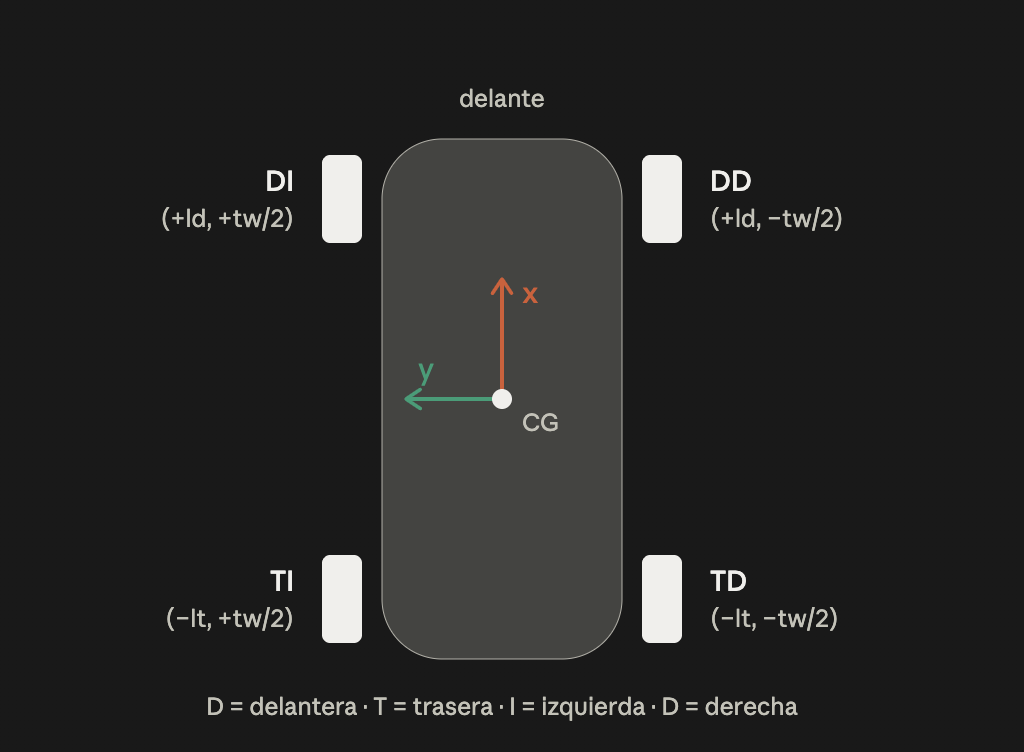

vx_c = max(vx, 1.0);                          % evita dividir por 0


%Fz de cada rueda

Fz_4 = ((p.m*p.g)/(2*L))*[p.lt;p.lt;p.ld;p.ld];

%Fuerzas al acelerar
Ra = 0.5*p.rho*p.Cd*p.Af*vx^2;
Rr = p.fr*p.m*p.g*cos(p.theta);
Rg = p.m*p.g*sin(p.theta);

%fuerzas de frenada limitantes
Fx_lim = ((p.mu_d + p.mu_t)/2)*p.m*p.g; % lo maximo que el agarre nos permite acelerar o frenar

ax_est = (max(min(Fx,Fx_lim),-Fx_lim) - Ra - sign(vx)*Rr - Rg)/p.m; %el min(max.. de abajo nos permite quedarnos con la fuerza real, es decir, la limite o la que nos dan el motor)
ay_est = vx*r; %solo centripeta                     %%ESTIMADAS

%sumatorio de fuerzas al acelerar
IncF_ac=((p.m*ax_est*p.h_cg)/(2*L))*[-1; -1; 1; 1];

%sumatorio de fuerzas al girar
IncF_gir=((p.m*ay_est*p.h_cg)/(2*p.distruedas))*[-1;1;-1;1];


Fz=max(Fz_4 + IncF_ac + IncF_gir,0); %puede que salga negativa, eso esq la rueda no esta tocando el suelo, se cambia por 0 si sale en la simulación.


%velocidad en x de cada una de las reudas, debido a que al girar, unas
%giran más que otras
vruedas_x = vx_c - r*Yw; %velocidad de cada rueda independiente

%velocidad en y
vruedas_y = vy + Xw*r;

%asi podemos sacar la deriva
delta4=[delta; delta; 0; 0];
alpha4=delta4 - vruedas_y./vruedas_x;


%Fuerza lateral de cada rueda

% cada rueda tiene su propia rigidez, partiendo de Cad y Cat tenemos que
% sacar las 4 ruedas

Ca4=0.5*[p.Cad;p.Cad;p.Cat;p.Cat];

Fy4=Ca4.*alpha4;

%Fuerza longitudinal, como sabemos, cuando aceleramos el peso se va hacia
%atrás y nos permite
%acelerar mas con las ruedas traseras pero por lo tanto, tenemos menos
%agarre en las ruedas delanteras

%calculamos el porcentaje de peso que se queda delante y el que se va para
%atrás


%en un coche normal
Kdel=(Fz(1)+Fz(2))/sum(Fz); %peso delante/peso total

Ktras=1-Kdel;       %así distribuimos el peso delante y atrás, y ahora rueda por rueda

IncFruedas = Mz/(2*p.distruedas); % el controlador calcula Mz y luego nosotros a traves de ahí sabemos cuanta Fx hay que mandarle a las ruedas

Fx4 = (Fx/2)*[Kdel Kdel Ktras Ktras]' + IncFruedas*[-1 1 -1 1]';

Fx4 = max(min(Fx4,p.Fx_motor_max),-p.Fx_regen_max);  %de aquí nos guardamos de que no se pase de la fx maxima que puede hacer el motor


%ahora entramos en el circulo de fricción

mu4=[p.mu_d; p.mu_d; p.mu_t; p.mu_t]; %las adherencias de las 4 ruedas
Fmax4=mu4.*Fz;   %Fuerza máx limitada por la adherencia y Fz
Ftot4=sqrt(Fx4.^2+Fy4.^2); %La fuerza total que se ejerce desde Fx y Fy, partiendo del circulo de frición

k4=min(1,Fmax4./max(Ftot4,1e-6)); % si el punto se sale del circulo, se queda en el borde (1), sino pues le da lo que esta pidiendo

Fx4 = k4.*Fx4;
Fy4 = k4.*Fy4;


% Ecuaciones del movimiento
ax = (sum(Fx4) - Ra - sign(vx)*Rr - Rg)/p.m + vy*r;
ay = sum(Fy4)/p.m - vx*r;
dr = (sum(Xw.*Fy4)-sum(Yw.*Fx4))/p.Iz;

% Integración (Euler)
vx_next  = max(vx + ax*dt, 0);
vy_next  = vy + ay*dt;
r_next   = r + dr*dt;
X_next   = X + (vx*cos(psi) - vy*sin(psi))*dt;
Y_next   = Y + (vx*sin(psi) + vy*cos(psi))*dt;
psi_next = psi + r*dt;
z_next = [X_next; Y_next; psi_next; vx_next; vy_next; r_next];
end